clear

## **Lista de Funções:**

r = @(x) 100*(x(2)-x(1)^2)^2 + (1-x(1))^2;
g = @(x) x(1)*(x(1) + 3)*(x(1) - 3)*(x(1) - 5) + x(2)*(x(2) + 3)*(x(2) - 3)*(x(2) - 5);
f = @(x) ((x(1))^2 - 100)*((x(1))^2 - 61) + ((x(2))^2 - 25)*((x(2))^2 - 16) - 15*cos(x(1)-(7/5))*cos(x(2)-(9/2));

## Teste 1 - Função matemática g(x)

disp("--------------- Variveis globais --------------");

--------------- Variveis globais --------------


Nvar = 2;
Nmax = randi([35,50])

Nmax = 44

errodf = 15e-2

errodf = 0.1500

NPontosIniciais = randi([8,13])

NPontosIniciais = 8

x_values=[-11;-11]; y_values=[7;7];
lambda = 0.0005

lambda = 5.0000e-04


disp("------------------- Outputs -------------------");

------------------- Outputs -------------------


    
PontosIniciais = getNPontosIniciais(NPontosIniciais, Nvar,x_values,y_values);
tic;
[Lista, LNit, Lopt, dffinal] = steepest_descent_static(g, Nmax, errodf, PontosIniciais, x_values, y_values, lambda);
tempo_execucao_teste1 = toc

tempo_execucao_teste1 = 5.3857

xopt_teste1 = minGlobal(Lopt, g)

xopt_teste1 =    -2.1247
   -2.0497


taxa_media_convergencia_teste1 = taxaMediaConvergencia(LNit)

taxa_media_convergencia_teste1 = 44

tipo_convergencia_teste1 = tipoConvergencia(dffinal, errodf, Nmax)

tipo_convergencia_teste1 = 'Convergência para um mínimo local'

[minimos_locais_teste1, minimizantes_locais_teste1] = minimosMinimizantesLocais(Lopt, g)

minimos_locais_teste1 =     2.9749   -2.1247
   -2.1331   -2.0497


minimizantes_locais_teste1 =   -66.8049 -137.2430


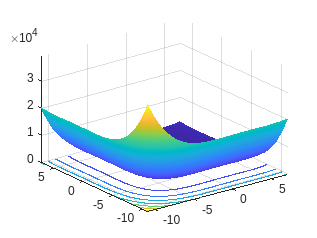

close all

nivelGraficos(g,x_values(1),y_values(1),x_values(2),y_values(2))

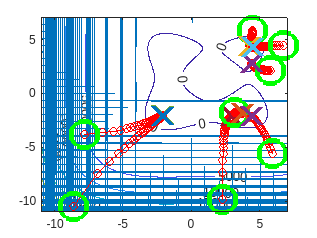


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

## Teste 2- Função de Rosenbrock

lambda = 0.000005;
disp("---------------------- // ----------------------")

---------------------- // ----------------------



tic; 
[Lista, LNit, Lopt, dffinal] = steepest_descent_static(r, Nmax, errodf, PontosIniciais, x_values, y_values, lambda);
tempo_execucao_teste2 = toc

tempo_execucao_teste2 = 5.5491

xopt_teste2 = minGlobal(Lopt, r)

xopt_teste2 =     2.8144
    6.0507


taxa_media_convergencia_teste2 = taxaMediaConvergencia(LNit)

taxa_media_convergencia_teste2 = 44

tipo_convergencia_teste2 = tipoConvergencia(dffinal, errodf, Nmax)

tipo_convergencia_teste2 = 'Convergência para um mínimo local'

[minimos_locais_teste2, minimizantes_locais_teste2] = minimosMinimizantesLocais(Lopt, r)

minimos_locais_teste2 =     2.8144
    6.0507


minimizantes_locais_teste2 = 353.0252

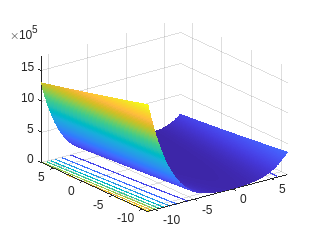

close all

nivelGraficos(r,x_values(1),y_values(1),x_values(2),y_values(2))

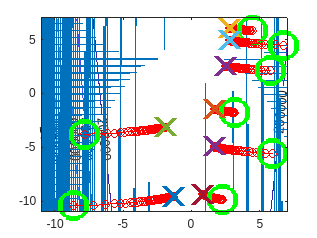


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

## Teste 3- Função matemática f(x)

disp("---------------------- // ----------------------")

---------------------- // ----------------------


disp("Nesta funçao consideramos alterar o valor; devido a erros")

Nesta funçao consideramos alterar o valor; devido a erros


lambda = 0.0005;

tic;
[Lista, LNit, Lopt, dffinal] = steepest_descent_static(f, Nmax, errodf, PontosIniciais, x_values, y_values, lambda);
tempo_execucao_teste3 = toc

tempo_execucao_teste3 = 6.1986

xopt_teste3 = minGlobal(Lopt, f)

xopt_teste3 =    -8.9549
   -4.5294


taxa_media_convergencia_teste3 = taxaMediaConvergencia(LNit)

taxa_media_convergencia_teste3 = 44

tipo_convergencia_teste3 = tipoConvergencia(dffinal, errodf, Nmax)

tipo_convergencia_teste3 = 'Convergência para um mínimo local'

[minimos_locais_teste3, minimizantes_locais_teste3] = minimosMinimizantesLocais(Lopt, f)

minimos_locais_teste3 =     8.9499   -8.9549
    4.5254   -4.5294


minimizantes_locais_teste3 =  -404.8300 -408.6782


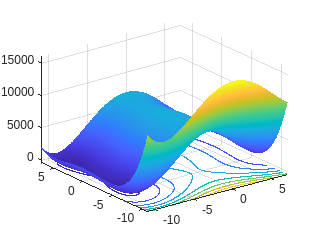

close all

nivelGraficos(f,x_values(1),y_values(1),x_values(2),y_values(2))

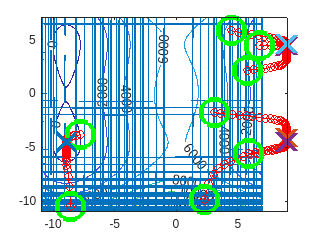


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

T = table([tempo_execucao_teste1; tempo_execucao_teste2; tempo_execucao_teste3], ...
          [taxa_media_convergencia_teste1; taxa_media_convergencia_teste2; taxa_media_convergencia_teste3], ...
          {tipo_convergencia_teste1; tipo_convergencia_teste2; tipo_convergencia_teste3}, ...
          'VariableNames', {'Tempo de Execucao', 'Taxa Media de Convergencia', 'Tipo de Convergencia'}, ...
          'RowNames', {'Teste1', 'Teste2', 'Teste3'});

disp(T);

              Tempo de Execucao    Taxa Media de Convergencia            Tipo de Convergencia         
              _________________    __________________________    _____________________________________

    Teste1         5.3857                      44                {'Convergência para um mínimo local'}
    Teste2         5.5491                      44                {'Convergência para um mínimo local'}
    Teste3         6.1986                      44                {'Convergência para um mínimo local'}

